# Plan kurvebevægelse

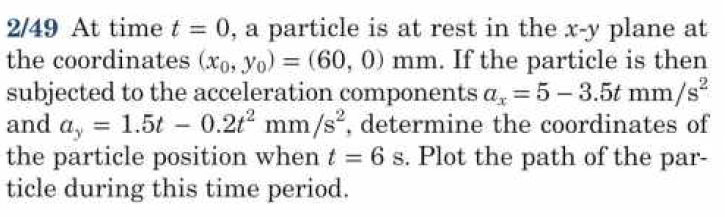

clear

u = symunit;

x0 = 60 

x0 = 60

y0 = 0

y0 = 0


syms t

ax = 5 - 3.5*t 

$$ax = 5-\frac{7\,t}{2}$$

vx = int(ax,t)

$$vx = -\frac{t\,\left(7\,t-20\right)}{4}$$

px = int(vx, t) + x0

$$px = 60-\frac{t^{2}\,\left(7\,t-30\right)}{12}$$



ay = 1.5*t - 0.2*t^2

$$ay = \frac{3\,t}{2}-\frac{t^{2}}{5}$$

vy = int(ay,t)

$$vy = -\frac{t^{2}\,\left(4\,t-45\right)}{60}$$

py = int(vy, t)

$$py = -\frac{t^{3}\,\left(t-15\right)}{60}$$


py1 = subs(py,t,6);
vpa(py1,3)

$$ans = 32.4$$

px1 = subs(px,t,6);
vpa(px1,3)

$$ans = 24.0$$

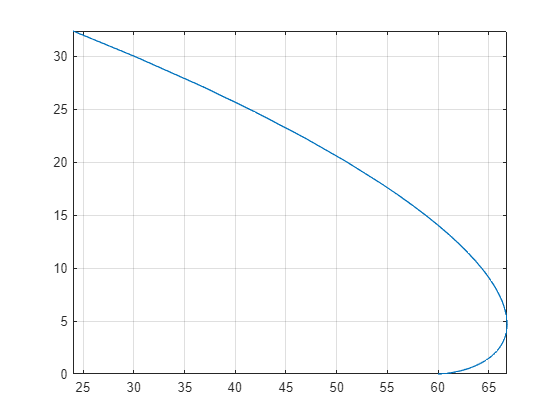



fplot(px,py, [0,6]), grid()

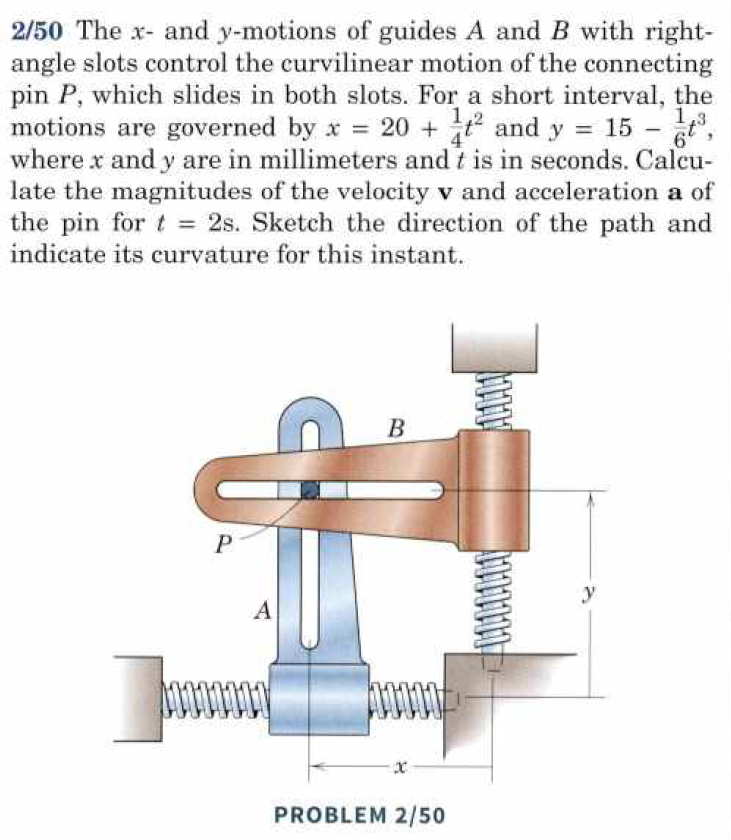

clear

syms t

px = 20 + 1/4 * t^2

$$px = \frac{t^{2}}{4}+20$$

vx = diff(px,t)

$$vx = \frac{t}{2}$$

ax = diff(vx,t)

$$ax = \frac{1}{2}$$


py = 15 - 1/6 * t^3

$$py = 15-\frac{t^{3}}{6}$$

vy = diff(py,t)

$$vy = -\frac{t^{2}}{2}$$

ay = diff(vy,t)

$$ay = -t$$


t_ny = 2

t_ny = 2


v_avg = sqrt(vx^2 + vy^2);
v_avg = vpa(subs(v_avg,t,t_ny),3)

$$v\_avg = 2.24$$


a_avg = sqrt(ax^2 + ay^2);
a_avg = vpa(subs(a_avg,t,t_ny),3)

$$a\_avg = 2.06$$

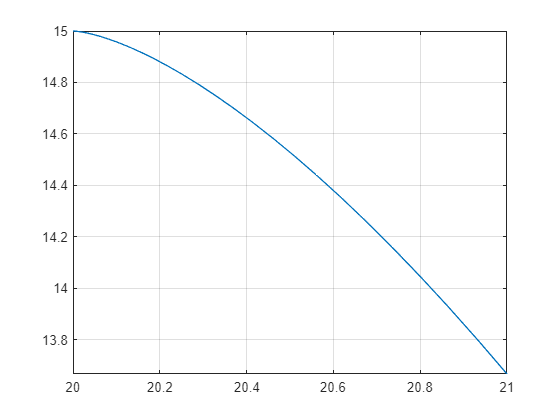





fplot(px,py,[0 2]), grid()